clear
clc
close all

ModularAplysia_1282022_withSNS_initialization;
load("params_1282022.mat")
endTime = 200;

## Biting

MechanicsParaOriginal;
InitPara;
CtrlParaSNSTuning;
max_I3ant = 1.2;
seaweed_strength = 10;

mu_s_g = 0;
mu_k_g = 0;
mu_s_h = 0;
mu_k_h = 0;

sens_chemical_lips = 1;
sens_mechanical_lips = 1;
sens_mechanical_grasper = 0;
fixation_type = 1;
simout_biting_fb = sim('ModularAplysia_1282022_withSNS_originalMechanics.slx', 'StopTime',string(endTime),'MinStep','0.001');



k_xgh_B64_1 = 0;
k_xgh_B64_2 = 0;
k_xgh_B38 = 0;
k_xgh_B7_1 = 0;
k_xgh_B7_2 = 0;
k_xgh_B4 = 0;
k_sens_mechanical_grasper_B4 = 0;
k_sens_mechanical_grasper_B38 = 0;
k_sens_mechanical_lip_B38 = 0;
k_sens_chemical_lip_B38 = 0;

fixation_type = 1;
simout_biting_ff = sim('ModularAplysia_1282022_withSNS_originalMechanics.slx', 'StopTime',string(endTime),'MinStep','0.001');

## Swallowing

MechanicsParaOriginal;
CtrlParaSNSTuning;
% mu_s_g = 0.43;
% mu_k_g = 0.3;
% mu_s_h = 0.3;
% mu_k_h = 0.3;
% max_I3ant = 1.2;
mu_s_g = 0.45;
mu_k_g = 0.3;
mu_s_h = 0.3;
mu_k_h = 0.3;
max_I3ant = 1.2;
seaweed_strength = 10;

sens_chemical_lips = 1;
sens_mechanical_lips = 1;
sens_mechanical_grasper = 1;
fixation_type = 1;
% gsyn_B342B64fi = 0.15;
% gsyn_B402B64fi = 0.18;
simout_swallowing_load = sim('ModularAplysia_1282022_withSNS_originalMechanics.slx', 'StopTime',string(endTime),'MinStep','0.001');


fixation_type = 0;
% gsyn_B342B64fi = 0.15;
% gsyn_B402B64fi = 0.18;
simout_swallowing_unload = sim('ModularAplysia_1282022_withSNS_originalMechanics.slx', 'StopTime',string(endTime),'MinStep','0.001');

## Process Data

timespan = 30;
timebeginuntil = 150;

[protractionRectangles_biting_fb,~] = prorec(simout_biting_fb,timespan,timebeginuntil);
produration_biting_fb = simout_biting_fb.tout(protractionRectangles_biting_fb(1,2)) - simout_biting_fb.tout(protractionRectangles_biting_fb(1,1));
reduration_biting_fb = simout_biting_fb.tout(protractionRectangles_biting_fb(2,1)) - simout_biting_fb.tout(protractionRectangles_biting_fb(1,2));

[protractionRectangles_biting_ff,~] = prorec(simout_biting_ff,timespan,timebeginuntil);
produration_biting_ff = simout_biting_ff.tout(protractionRectangles_biting_ff(1,2)) - simout_biting_ff.tout(protractionRectangles_biting_ff(1,1));
reduration_biting_ff = simout_biting_ff.tout(protractionRectangles_biting_ff(2,1)) - simout_biting_ff.tout(protractionRectangles_biting_ff(1,2));

[protractionRectangles_swallowing_load,~] = prorec(simout_swallowing_load,timespan,timebeginuntil);
produration_swallowing_load = simout_swallowing_load.tout(protractionRectangles_swallowing_load(1,2)) - simout_swallowing_load.tout(protractionRectangles_swallowing_load(1,1));
reduration_swallowing_load = simout_swallowing_load.tout(protractionRectangles_swallowing_load(2,1)) - simout_swallowing_load.tout(protractionRectangles_swallowing_load(1,2));

[protractionRectangles_swallowing_unload,~] = prorec(simout_swallowing_unload,timespan,timebeginuntil);
produration_swallowing_unload = simout_swallowing_unload.tout(protractionRectangles_swallowing_unload(1,2)) - simout_swallowing_unload.tout(protractionRectangles_swallowing_unload(1,1));
reduration_swallowing_unload = simout_swallowing_unload.tout(protractionRectangles_swallowing_unload(2,1)) - simout_swallowing_unload.tout(protractionRectangles_swallowing_unload(1,2));


## Plot Parameters

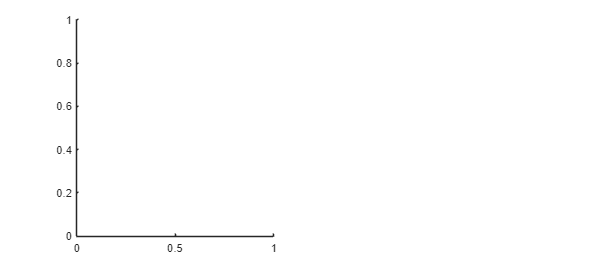

figure
figuresize = get(gcf,'position');
figuresize = [0,0, 840 * 0.78,294];
% figuresize = figuresize.*[1,1,1.2,1];
set(gcf,'position',figuresize);
set(gcf,'Color','white')
subplot(1,2,1)

position = get(gca,'position');
left = 0.1;
bottom = position(2) - 0.05*position(4);
width = position(3)*0.625;
height = position(4)*0.64*10/7;
% leftshift = 0.8*width;
leftshift = 0.8*width;
deltaleft = 1/20*width;
deltabottom = deltaleft*figuresize(3)/figuresize(4);
yrange = [0,22];
barcolorset = {[0.8,0.8,0.8],[1/3,1/3,1/3]};
errorcolorset = {[0,0,0],[0.5,0.5,0.5]};
errcapsize = 10;
errwidth = 1;
tickwidth = 1;
fontsize = 8;
barwidth = 0.8;

## Yaxis

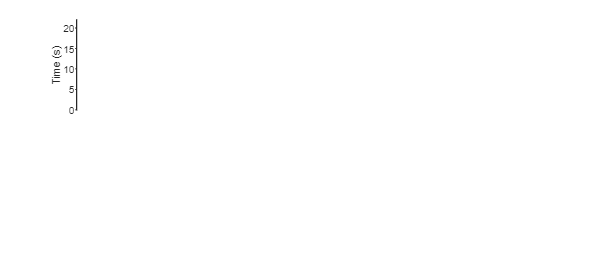

ax11 = subplot(2,5,1);
ylim(yrange)
ylabel('Time (s)')
set(gca,'box','off','XColor','none','ytick',0:5:yrange(2),...
    'TickDir','out','LineWidth',tickwidth,'TickLength',[0.0086,0.0086],...
    'FontSize',fontsize,'Color','none')

## Biting with Feedback

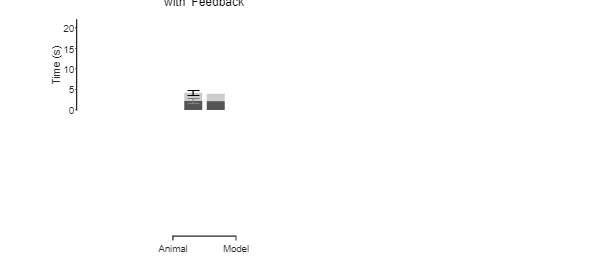

ax12 = subplot(2,5,2);
X = categorical({'Animal','Model'});
% Y = [2.03,2.17;produration_biting_fb,reduration_biting_fb];
Y = [2.17,2.03;reduration_biting_fb,produration_biting_fb];
b = bar(X,Y,'stacked','BarWidth',barwidth,'LineStyle','none');

% std = [0.62,0.60];
std = [0.60,0.62];
x = vertcat(b.XEndPoints)'; 
y = vertcat(b.YEndPoints)';
hold on
errorbar(x(1,1),y(1,1),std(1),'Color',errorcolorset{2},'linestyle','none',...
    'HandleVisibility','off','LineWidth',errwidth,'CapSize',errcapsize);
errorbar(x(1,2),y(1,2),std(2),'Color',errorcolorset{1},'linestyle','none',...
    'HandleVisibility','off','LineWidth',errwidth,'CapSize',errcapsize);  

b(1).FaceColor = 'flat';
b(2).FaceColor = 'flat';
b(1).CData = barcolorset{2};
b(2).CData = barcolorset{1};
ylim(yrange)
set(gca,'FontSize',fontsize,'box','off','XColor','none',...
    'YColor','none','XTick',[],'XTickLabel',[],'Color','none')
title({'(\bfA\rm) Biting','with Feedback'},'FontWeight','normal','FontSize',10,'Position',[1.5,1.1*yrange(2)])

ax22 = subplot(2,5,7);
xlim([0,1])
xticks([0,1])
xticklabels({'Animal','Model'})
xtickangle(0)
set(gca,'FontSize',fontsize,'TickDir','out','LineWidth',tickwidth,...
    'TickLength',[0.0398,0.0398],'box','off','YColor','none','Color','none')

## Biting without Feedback

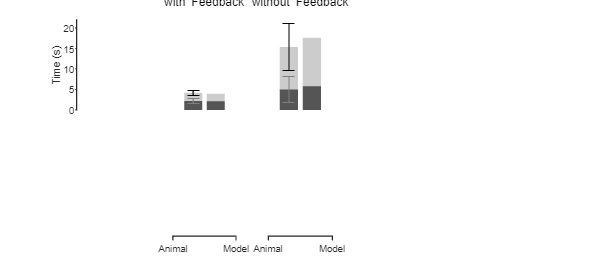

ax13 = subplot(2,5,3);
X = categorical({'Animal','Model'});
% Y = [10.40,4.99;produration_biting_ff,reduration_biting_ff];
Y = [4.99,10.40;reduration_biting_ff,produration_biting_ff];
b = bar(X,Y,'stacked','BarWidth',barwidth,'LineStyle','none');

% std = [5.78,3.28];
std = [3.28,5.78];
x = vertcat(b.XEndPoints)'; 
y = vertcat(b.YEndPoints)';
hold on
errorbar(x(1,1),y(1,1),std(1),'Color',errorcolorset{2},'linestyle','none',...
    'HandleVisibility','off','LineWidth',errwidth,'CapSize',errcapsize);
errorbar(x(1,2),y(1,2),std(2),'Color',errorcolorset{1},'linestyle','none',...
    'HandleVisibility','off','LineWidth',errwidth,'CapSize',errcapsize);   

b(1).FaceColor = 'flat';
b(2).FaceColor = 'flat';
b(1).CData = barcolorset{2};
b(2).CData = barcolorset{1};
ylim(yrange)
set(gca,'FontSize',fontsize,'box','off','XColor','none',...
    'YColor','none','XTick',[],'XTickLabel',[],'Color','none')
title({'(\bfB\rm) Biting','without Feedback'},'FontWeight','normal','FontSize',10,'Position',[1.5,1.1*yrange(2)])

ax23 = subplot(2,5,8);
xlim([0,1])
xticks([0,1])
xticklabels({'Animal','Model'})
xtickangle(0)
set(gca,'FontSize',fontsize,'TickDir','out','LineWidth',tickwidth,...
    'TickLength',[0.0398,0.0398],'box','off','YColor','none','Color','none')
set(b(1),'clipping','off')% turn off clippings
set(b(2),'clipping','off')% turn off clippings

## unLoaded Swallow

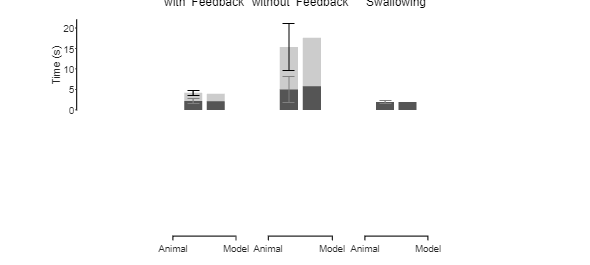

ax14 = subplot(2,5,4);
X = categorical({'Animal','Model'});
Y = [1.94;reduration_swallowing_unload];
b = bar(X,Y,'stacked','BarWidth',barwidth,'LineStyle','none');
std = 0.36;
x = vertcat(b.XEndPoints)'; 
y = vertcat(b.YEndPoints)';
hold on
errorbar(x(1,1),y(1,1),std(1),'Color',errorcolorset{2},'linestyle','none',...
    'HandleVisibility','off','LineWidth',errwidth,'CapSize',errcapsize);
b(1).FaceColor = 'flat';
b(1).CData = barcolorset{2};

ylim(yrange)
set(gca,'FontSize',fontsize,'box','off','XColor','none',...
    'YColor','none','XTick',[],'XTickLabel',[],'Color','none')
title({'(\bfC\rm) Unloaded','Swallowing'},'FontWeight','normal','FontSize',10,'Position',[1.5,1.1*yrange(2)])

ax24 = subplot(2,5,9);
xlim([0,1])
xticks([0,1])
xticklabels({'Animal','Model'})
xtickangle(0)
set(gca,'FontSize',fontsize,'TickDir','out','LineWidth',tickwidth,...
    'TickLength',[0.0398,0.0398],'box','off','YColor','none','Color','none')

## Loaded Swallow

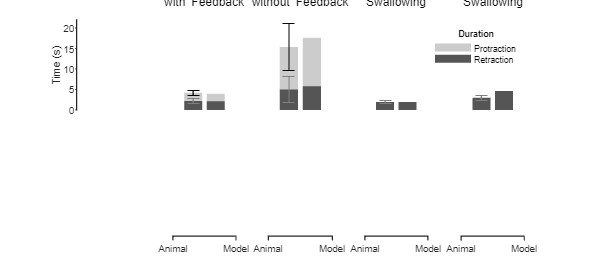

ax15 = subplot(2,5,5);
X = categorical({'Animal','Model'});
Y = [2.96,0;reduration_swallowing_load,0];
b = bar(X,Y,'stacked','BarWidth',barwidth,'LineStyle','none');
std = 0.69;
x = vertcat(b.XEndPoints)'; 
y = vertcat(b.YEndPoints)';
hold on
errorbar(x(1,1),y(1,1),std(1),'Color',errorcolorset{2},'linestyle','none',...
    'HandleVisibility','off','LineWidth',errwidth,'CapSize',errcapsize);
b(1).FaceColor = 'flat';
b(1).CData = barcolorset{2};
b(2).FaceColor = 'flat';
b(2).CData = barcolorset{1};

ylim(yrange)
set(gca,'FontSize',fontsize,'box','off','XColor','none',...
    'YColor','none','XTick',[],'XTickLabel',[],'Color','none')
title({'(\bfD\rm) Loaded','Swallowing'},'FontWeight','normal','FontSize',10,'Position',[1.5,1.1*yrange(2)])
leg = legend('Retraction','Protraction');
title(leg,'Duration')
legend boxoff

ax25 = subplot(2,5,10);
xlim([0,1])
xticks([0,1])
xticklabels({'Animal','Model'})
xtickangle(0)
set(gca,'FontSize',fontsize,'TickDir','out','LineWidth',tickwidth,...
    'TickLength',[0.0398,0.0398],'box','off','YColor','none','Color','none')

## Reorganization

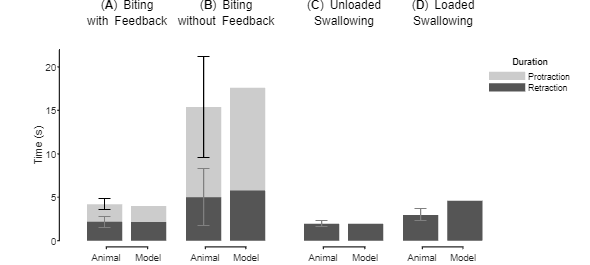

currentleft = left;
set(ax11,'position',[currentleft,bottom + deltabottom,1/40*width,height - deltabottom])
currentleft = left + deltaleft;
set(ax12,'position',[currentleft,bottom + deltabottom,width,height - deltabottom])
set(ax22,'position',[currentleft + width/3,bottom,1/3*width,1e-4*height])
currentleft = currentleft + leftshift;
set(ax13,'position',[currentleft,bottom + deltabottom,width,height - deltabottom])
set(ax23,'position',[currentleft + width/3,bottom,1/3*width,1e-4*height])
currentleft = currentleft + leftshift*1.2;
set(ax14,'position',[currentleft,bottom + deltabottom,width,height - deltabottom])
set(ax24,'position',[currentleft + width/3,bottom,1/3*width,1e-4*height])
currentleft = currentleft + leftshift;
set(ax15,'position',[currentleft,bottom + deltabottom,width,height - deltabottom])
set(ax25,'position',[currentleft + width/3,bottom,1/3*width,1e-4*height])

rect = leg.Position;
% rect(1) = 0.85;
rect(1) = 0.825;
set(leg,'Position',rect)

## Local Functions

function [protractionRectangles,index] = prorec(simout,timespan,timebeginuntil)
    startnum = 0;
    endnum = length(simout.tout);
    simout.xgh = simout.x_g.Data' - simout.x_h.Data';
    grasper_rel_pos = simout.xgh;
    numProtractionBoxes = 0;
    numRetractionBoxes = 0;
    protraction = 1;
    protractionRectangles=[0,0];
    retractionRectangles=[0,0];
    for ind=startnum+2:endnum
        if (grasper_rel_pos(ind) - grasper_rel_pos(ind-1))/(simout.tout(ind) - simout.tout(ind-1)) > 1e-8
            %protraction
            if(protraction == 0)
                numProtractionBoxes=numProtractionBoxes+1;
                protraction = 1;
                %end the last retractionrectangle
                if(numRetractionBoxes>0)
                    retractionRectangles(numRetractionBoxes,2) = ind;
                end
                %start a new protractionrectangle
                protractionRectangles(numProtractionBoxes,1) = ind;
            end
        else
            %retraction
            if(protraction == 1)
                numRetractionBoxes=numRetractionBoxes+1;
                protraction = 0;
                %end the last retractionrectangle
                retractionRectangles(numRetractionBoxes,1) = ind;
                %start a new protractionrectangle
                if(numProtractionBoxes>0)
                    protractionRectangles(numProtractionBoxes,2) = ind;
                end
            end
        end
    end
    
    if protractionRectangles(end,2) == 0
        protractionRectangles(end,2) = endnum;
    end
    
    k = 2;
    while 1
        if k > size(protractionRectangles,1)
            break;
        elseif simout.tout(protractionRectangles(k,1)) - simout.tout(protractionRectangles(k-1,2)) < 1.5
            protractionRectangles(k-1,2) = protractionRectangles(k,2);
            protractionRectangles(k,:) = [];
            continue;
        end
        k = k + 1;
    end

    k = 1;
    while 1
        if k > size(protractionRectangles,1)
            break;
        elseif simout.tout(protractionRectangles(k,2)) - simout.tout(protractionRectangles(k,1)) < 1
            protractionRectangles(k,:) = [];
            continue;
        end
        k = k + 1;
    end   

    protractionRectangles = protractionRectangles(simout.tout(protractionRectangles(:,1)) > timebeginuntil,:);
    
    beginindex = protractionRectangles(1,1);
    endindex = find(simout.tout >= simout.tout(beginindex) + timespan,1,'first');
    index = beginindex:endindex;
end